# 4-6-2016 - Multisubject Anova Analysis 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

% exclude playback for now
for i = 3:length(SIDS)-1
    sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
                        typeCell = {'180'};

        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2ePlaybackepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
            
    end
    
    
    
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{1});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = []; 
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                
                tB = [tB tempBase];
                t1 = [t1 tempResp1];
                t2 = [t2 tempResp2];
                t3 = [t3 tempResp3];
                
                
                
                %             elseif i == nullType && strcmp(sid,'ecb43e') == 0
                %                 tempMag = dataForAnova{chan}{i}{1};
                %                 tempLabel = dataForAnova{chan}{i}{2};
                %                 tempKeeps = dataForAnova{chan}{i}{3};
                %
                %                 tempBase = tempMag(tempLabel(tempKeeps)==0);
                %                 tempRespNull = tempMag(tempLabel(tempKeeps)==1);
                %
                %                 tN = [tN tempRespNull];
                
                
                
            
            lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
            vecType = repmat(typeCell{i},lengthType,1);
            vecTypeC = cellstr(vecType)';
            anovaType = [anovaType{:} vecTypeC];
            typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
            anovaTotalMags = [anovaTotalMags typeResp];
            num5S = repmat('Ct>=5',length(tempResp3),1);
            num3S= repmat('3<=Ct<=4',length(tempResp2),1);
            num1S = repmat('1<=Ct<=2',length(tempResp1),1);
            numBaseS = repmat('Base',length(tempBase),1);
            
            %             numNullS = repmat('Null',length(tN),1);
            
            b5C = cellstr(num5S)';
            b3C = cellstr(num3S)';
            b1C = cellstr(num1S)';
            BC = cellstr(numBaseS)';
%             nC = cellstr(numNullS)';
            anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        % change tihs to just to lnegth(t3) to do the one way anova below
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        %         num5S = repmat('Ct>=5',length(t3),1);
        %         num3S= repmat('3<=Ct<=4',length(t2),1);
        %         num1S = repmat('1<=Ct<=2',length(t1),1);
        %         numBaseS = repmat('Base',length(tB),1);
        %
        %         numNullS = repmat('Null',length(tN),1);
        %
        
        sidCell = cellstr(sidString)';
        %         b5C = cellstr(num5S)';
        %         b3C = cellstr(num3S)';
        %         b1C = cellstr(num1S)';
        %         BC = cellstr(numBaseS)';
        %         nC = cellstr(numNullS)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
%         anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
        %         anovaTotalMags = [anovaTotalMags t3 t2 t1 tB];
        %         anovaType = [anovaType typeNums];
        
        
    end
end

sid = c91479

sid = 7dbdec

sid = 9ab7ab

sid = 702d24

sid = ecb43e

sid = 0b5a2e

%     [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)
%     [c,m,h,gnames] = multcompare(stats);


p =        NaN
       NaN
       NaN
    0.0521
    0.0000
    0.0893


tbl =     'Source'                        'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'    'F'          'Prob>F'    
    'anovaNumStims'                 [         0]    [   0]    [        1]    [       0]    [      0]    [       NaN]
    'anovaType'                     [         0]    [   0]    [        1]    [       0]    [      0]    [       NaN]
    'anovaBetaSID'                  [         0]    [   0]    [        1]    [       0]    [      0]    [       NaN]
    'anovaNumStims*anovaType'       [   74.1591]    [   9]    [        1]    [  8.2399]    [ 1.8668]    [    0.0521]
    'anovaNumStims*anovaBetaSID'    [  642.5463]    [  12]    [        1]    [ 53.5455]    [12.1309]    [7.7368e-25]
    'anovaType*anovaBetaSID'        [   21.3354]    [   2]    [        1]    [ 10.6677]    [ 2.4168]    [    0.0893]
    'Error'                         [3.6693e+04]    [8313]    [        0]    [  4.4140]           []              []
    'Total'                         [1.5523e+05]    [8350]

stats =          source: 'anovan'
          resid: [8351x1 double]
         coeffs: [90x1 double]
            Rtr: [60x38 double]
       rowbasis: [38x90 double]
            dfe: 8313
            mse: 4.4140
    nullproject: [90x60 double]
          terms: [6x3 double]
        nlevels: [3x1 double]
     continuous: [0 0 0]
         vmeans: [3x1 double]
       termcols: [7x1 double]
     coeffnames: {90x1 cell}
           vars: [90x3 double]
       varnames: {3x1 cell}
       grpnames: {3x1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


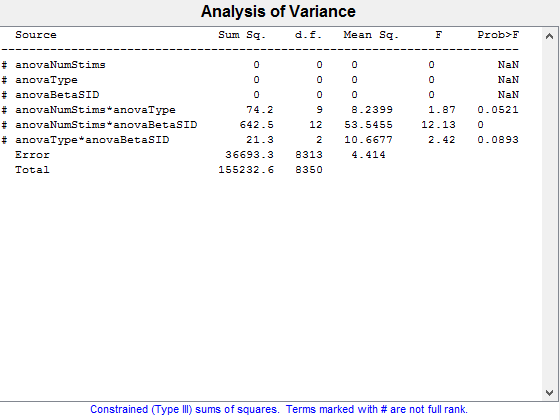

figure
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'},'model','interaction','nested',[0 1 1;0 0 1;0 0 0],'sstype',3)
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaType,anovaBetaSID},'varnames',{'anovaType','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])
[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'})

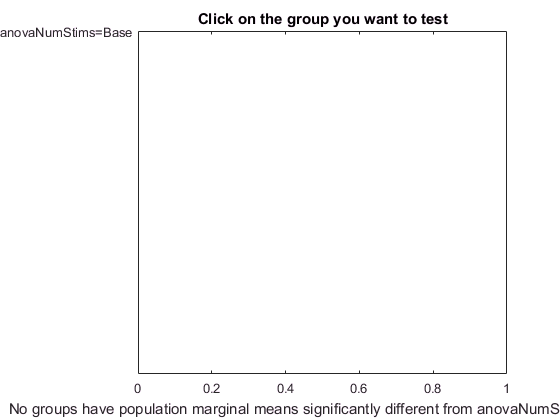

c =      1     2   NaN   NaN   NaN     1
     1     3   NaN   NaN   NaN     1
     1     4   NaN   NaN   NaN     1
     2     3   NaN   NaN   NaN     1
     2     4   NaN   NaN   NaN     1
     3     4   NaN   NaN   NaN     1


m =    NaN   NaN
   NaN   NaN
   NaN   NaN
   NaN   NaN


h =   Figure (15: Multiple comparison of population marginal means) with properties:

      Number: 15
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


gnames =     'anovaNumStims=Ct>=5'
    'anovaNumStims=3<=Ct<=4'
    'anovaNumStims=1<=Ct<=2'
    'anovaNumStims=Base'


% 
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaType},'varnames',{'anovaType'})
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'})
% [p,tbl,stats] = anovan(anova2,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'})
% 

figure
[c,m,h,gnames] = multcompare(stats)

[gnames num2cell(m)]

ans =     'anovaNumStims=Ct>=5'       [NaN]    [NaN]
    'anovaNumStims=3<=Ct<=4'    [NaN]    [NaN]
    'anovaNumStims=1<=Ct<=2'    [NaN]    [NaN]
    'anovaNumStims=Base'        [NaN]    [NaN]


figure
% bar(m(:,1))
% hold on
errorbar((1:length(m(:,1))),flip(m(:,1)),flip(m(:,2)),'ro','linestyle','none','linew',2','color','r')
% xlabel('Patients and Task','fontsize',16,'fontweight','bold')
ylabel('Zscored CCEP Magnitude','fontsize',14,'fontweight','bold')
xlabel('Number of Conditioning Pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1224 0.7750 0.7994]
            Units: 'normalized'

  Show all properties


ax.XTick = [1 2 3 4]

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1224 0.7750 0.7994]
            Units: 'normalized'

  Show all properties


ax.XTickLabel = {'Baseline','1->2','3->4','>5' }

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1224 0.7750 0.7994]
            Units: 'normalized'

  Show all properties


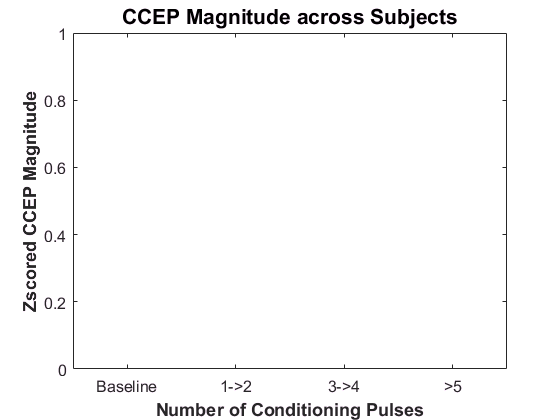

ax.FontSize = 12;
% ax.FontWeight = 'bold';
% set(gca,'XtickLabel',{'','>5','3->4', '1->2','Baseline'},'fontsize',14,'fontweight','bold')
title({'CCEP Magnitude across Subjects';},'fontsize',16,'fontweight','bold')

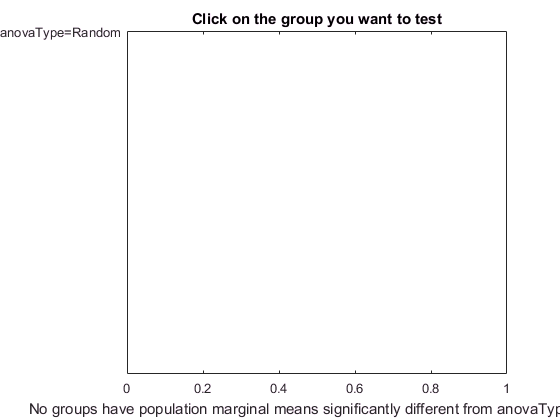

results1 =      1     2   NaN   NaN   NaN     1
     1     3   NaN   NaN   NaN     1
     1     4   NaN   NaN   NaN     1
     1     5   NaN   NaN   NaN     1
     2     3   NaN   NaN   NaN     1
     2     4   NaN   NaN   NaN     1
     2     5   NaN   NaN   NaN     1
     3     4   NaN   NaN   NaN     1
     3     5   NaN   NaN   NaN     1
     4     5   NaN   NaN   NaN     1



figure
results1 = multcompare(stats,'Dimension',[2])

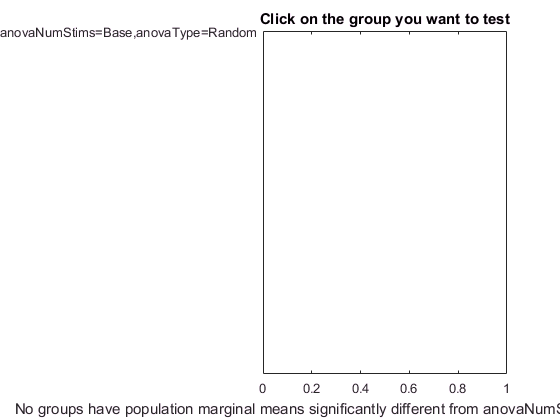

cM =      1     2   NaN   NaN   NaN     1
     1     3   NaN   NaN   NaN     1
     1     4   NaN   NaN   NaN     1
     1     5   NaN   NaN   NaN     1
     1     6   NaN   NaN   NaN     1
     1     7   NaN   NaN   NaN     1
     1     8   NaN   NaN   NaN     1
     1     9   NaN   NaN   NaN     1
     1    10   NaN   NaN   NaN     1
     1    11   NaN   NaN   NaN     1


mM =    NaN   NaN
   NaN   NaN
   NaN   NaN
   NaN   NaN
   NaN   NaN
   NaN   NaN
   NaN   NaN
   NaN   NaN
   NaN   NaN
   NaN   NaN


hM =   Figure (18: Multiple comparison of population marginal means) with properties:

      Number: 18
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


gnamesM =     'anovaNumStims=Ct>=5,anovaType=180'
    'anovaNumStims=3<=Ct<=4,anovaType=180'
    'anovaNumStims=1<=Ct<=2,anovaType=180'
    'anovaNumStims=Base,anovaType=180'
    'anovaNumStims=Ct>=5,anovaType=0'
    'anovaNumStims=3<=Ct<=4,anovaType=0'
    'anovaNumStims=1<=Ct<=2,anovaType=0'
    'anovaNumStims=Base,anovaType=0'
    'anovaNumStims=Ct>=5,anovaType=270'
    'anovaNumStims=3<=Ct<=4,anovaType=270'
    'anovaNumStims=1<=Ct<=2,anovaType=270'
    'anovaNumStims=Base,anovaType=270'
    'anovaNumStims=Ct>=5,anovaType=90'
    'anovaNumStims=3<=Ct<=4,anovaType=90'
    'anovaNumStims=1<=Ct<=2,anovaType=90'
    'anovaNumStims=Base,anovaType=90'
    'anovaNumStims=Ct>=5,anovaType=Random'
    'anovaNumStims=3<=Ct<=4,anovaType=Random'
    'anovaNumStims=1<=Ct<=2,anovaType=Random'
    'anovaNumStims=Base,anovaType=Random'




% figure
% results = multcompare(stats,'Dimension',[3])

figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 2])

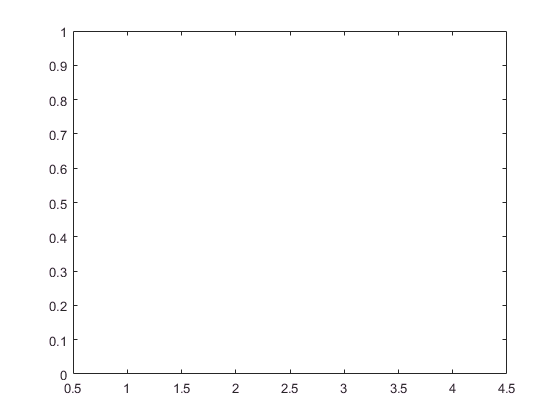

errorbar((1:length(m(:,1))),m(:,1),m(:,2),'ro','linestyle','none','linew',2','color','r')